clc, clear, close all
numSymPerFrame = 2^12;  % Кол-во КАМ символов в кадре
M = 16;                 % Глубина модуляции
k = log2(M);
filtlen = 64;           % Длина фильтра в символах
rolloff = 0.25;         % Коэффициент затухания фильтра
sps = 16;               % количества выборок на символ
fs = sps*4;             % частота дискретизации
fss = 0.1 * fs;         % Для управления смещением спм сигнала от 0 до 2pi
EbNoVec = (1:11);       % величина Eb/No (dB)
codeRate = 2/3;         % для кода со скоростью 2/3 с помощью функции poly2trellis. 
counter = 0;            % Счетчик для РУ
traceBack = 16;

%%ОСШ
snr = convertSNR(EbNoVec,"ebno","snr",BitsPerSymbol=k, ...
    SamplesPerSymbol=sps, CodingRate=codeRate);


berEst = zeros(size(EbNoVec));
for n = 1:length(snr)
    % Обнуление ошибок и бит
    numErrs = 0;
    numBits = 0;
    
    while numErrs < 10 || numBits < 1e3

%%ПРИЕМОПЕРЕДАЮЩИЙ МОДУЛЬ

%ВХОДНЫЕ ДАННЫЕ 1
        dataIn = randi([0 1],numSymPerFrame*k,1);

%РЕЗУЛЬТАТ 1

        [dataOut,txSigUp,tPoly] = Transceiver(dataIn,k,snr,M,rolloff,filtlen,sps,fs,fss,n,traceBack);

%РАССЧЕТ КОЛЛИЧЕСТВА ОШИБОЧНЫХ БИТ 1

        decDelay = 2*traceBack; %Задержка декодера [бит]
        if length(dataIn) > decDelay
            nErrors = biterr(dataIn(1:end - decDelay),dataOut(decDelay + 1:end));
        else
            nErrors = 0;
        end
        % Счетчики бит и ошибок
        numErrs = numErrs + nErrors;
        numBits = numBits + numSymPerFrame*k;
    end
    
%%ОЦЕНКА КОЭФФИЦИЕНТА БИТОВЫХ ОШИБОК 1

      berEst(n) = numErrs/numBits
end

berEst =     0.4991         0         0         0         0         0         0         0         0         0         0


berEst =     0.4991    0.4724         0         0         0         0         0         0         0         0         0


berEst =     0.4991    0.4724    0.4442         0         0         0         0         0         0         0         0


berEst =     0.4991    0.4724    0.4442    0.3742         0         0         0         0         0         0         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336         0         0         0         0         0         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336    0.1187         0         0         0         0         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336    0.1187    0.0385         0         0         0         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336    0.1187    0.0385    0.0026         0         0         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336    0.1187    0.0385    0.0026    0.0007         0         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336    0.1187    0.0385    0.0026    0.0007    0.0000         0


berEst =     0.4991    0.4724    0.4442    0.3742    0.2336    0.1187    0.0385    0.0026    0.0007    0.0000    0.0000


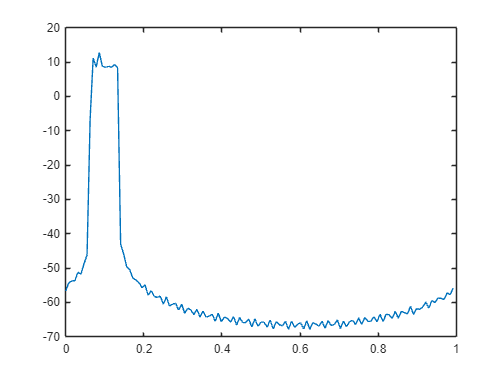


%%ОЦЕНКА СПМ МЕТОДОМ УЭЛЧА

[pxx,wx] = pwelch(txSigUp,[],[],128,[]); %Второе значение - размер окна, третье - прекрытие окон, 
        % четвертое - количество ДПФ преобразований (разделений на них), пятое - указание на какой частоте СПМ
plot(wx,10*log10(pxx))


%%ТЕОРЕТИЧЕСКИЕ ЗНАЧЕНИЯ КБО С АБГШ КАНАЛОМ

berTheoryawgn = berawgn(EbNoVec,'qam',M);
semilogy(EbNoVec,berEst,'*')
hold on
semilogy(EbNoVec,berTheoryawgn)
hold on
spect = distspec(tPoly,8);

%%ТЕОРЕТИЧЕСКИЕ ЗНАЧЕНИЯ КБО С КОДЕРОМ КАНАЛА:

berTheoryCoded = bercoding(EbNoVec,'conv','hard',codeRate,spect,'qam',M,'nondiff')

berTheoryCoded =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.1524    0.0159    0.0012    0.0001    0.0000


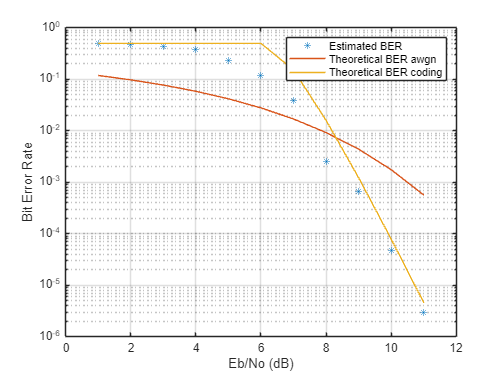

semilogy(EbNoVec,berTheoryCoded)
grid
legend('Estimated BER','Theoretical BER awgn','Theoretical BER coding')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')


%%РУ 
%работает, но увеличивает длительность рассчетов >100 раз

        %scope  = timescope('SampleRate',Fs,...
        %    'TimeSpanOverrunAction','Scroll',...
        %    'TimeSpanSource','Property','TimeSpan',100,...
        %    'ShowGrid',true,'LayoutDimensions',[3 1],'NumInputPorts',3);
        %scope.ActiveDisplay = 1;
        %scope.YLimits = [0 5];
        %scope.Title = 'Input Signal';
        %scope.ActiveDisplay = 2;
        %scope.YLimits = [0 350];
        %scope.Title = 'Compare Signal Energy with a Threshold';
        %scope.ActiveDisplay = 3;
        %scope.YLimits = [0 2];
        %scope.PlotType = 'Stairs';
        %scope.Title = 'Detect When Signal Energy Is Greater Than the Threshold';
        %threshold = 30; %Порог определения
        %FrameLength = 20;
        %Fs = 100;
        %movrmsWin = dsp.MovingRMS(20);
        %for index = 1:length(rxSig)
        %    V = rxSig(index);
        %    for i = 1:90
        %        x = V + 0.1 * randn(FrameLength,1);
        %        y1 = movrmsWin(x);
        %        y1ener = (y1(end)^2)*FrameLength;
        %        event = (y1ener>threshold);
        %        %if event == 1
        %        %    counter = counter + 1 %счетчик для опеределения верности
        %        %    детектирования не на глаз с учетом частоты дискретизации 
        %        %end
        %        
        %    end
        %end

function [dataOut,txSigUp,tPoly] = Transceiver(dataIn,k,snr,M,rolloff,filtlen,sps,fs,fss,n,traceBack)
%%ПЕРЕДАТЧИК

        %rng default  % одинаковые значения генерации для проверки
        % Генерация данных в двоичной СЧ и их перевод в символы
        
        
        

%%ПРИМЕНЕНИЕ СВЕРТОЧНОГО КОДА:

        constrlen = [5 4];           % Длина кодового ограничения
        genpoly = [23 35 0; 0 5 13]; % Создание Полиномов

        tPoly = poly2trellis(constrlen,genpoly); %Определение решетки сверточного кодирования                                         
        
%%КОДИРОВАНИЕ ВХОДНЫХ ДАННЫХ:

        dataEnc = convenc(dataIn,tPoly);
        dataSym = bit2int(dataEnc,k);
        
%%КАМ 
        txSig = qammod(dataSym,M);


%%СОЗДАНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА: 
        
        rrcFilter = rcosdesign(rolloff,filtlen,sps); % функция для создания фильтра Прип.Кос.
        txSignal = upfirdn(txSig,rrcFilter,sps,1);
        

%%%ПРОХОЖДЕНИЕ ЧЕРЕЗ СМЕСИТЕЛЬ
   
       ts = (0:length(txSignal)-1)/fs;
       fc = exp(1i * 2 * pi * fss * ts.');           % Частота гетеродина [Гц]
       
       txSigUp = txSignal.*fc; 
      
%%%КАНАЛ

%ПРОХРЖДЕНИЕ ЧЕРЕЗ АБГШ
        rxSig = awgn(txSigUp,snr(n),'measured');


%%ПРИЕМНИК

%%СМЕСИТЕЛЬ

        rxSigdown = rxSig .* exp(-1i * 2 * pi * fss * ts.');

%%ФИЛЬТР ПРИПОДНЯТОГО КОСИНУСА
        rxFiltSignal = ...
            upfirdn(rxSigdown,rrcFilter,1,sps);       % Уменьшениче частоты дисркетизации и фильтрация
        rxFiltSignal = ...
            rxFiltSignal(filtlen + 1:end - filtlen); 
     
%ДЕМОДУЛЯТОР КАМ
        rxSym = qamdemod(rxFiltSignal,M);
        rxSym = rxSym(:);
%ПЕРЕВОД СИМВОЛОВ В БИТЫ
        codedDataOut = int2bit(rxSym,k);                     
        numCodeWords = ...
            floor(length(codedDataOut)*2/3); % Количество полных кодовых слов
        dataOut = ...
            vitdec(codedDataOut(1:numCodeWords*3/2), ...
            tPoly,traceBack,'cont','hard');  % Декодирование данных
end


